# LTI اتصال سیستم های

## اتصال سری

برای تعریف اتصال زیر

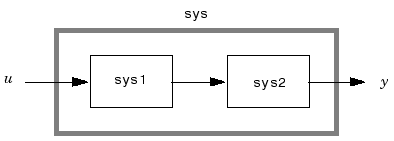

میتوانید از سینتکس های زیر استفاده کنید

`sys = series(sys1,sys2)`

`sys = sys1 * sys2`

#### مثال


$$G_1 =\frac{s^2 +3s+2}{s^3 +2s^2 +3s+1},G_2 =\frac{s+2}{s^2 +4s+3}$$


s = tf('s');
sys1 = (s^2 + 3*s + 2) / (s^3 + 2 * s^2 + 3 * s + 1);
sys2 = (s + 2) / (s^2 + 4 * s + 3);
sys = series(sys1, sys2)

sys =
 
           s^3 + 5 s^2 + 8 s + 4
  ----------------------------------------
  s^5 + 6 s^4 + 14 s^3 + 19 s^2 + 13 s + 3
 
Continuous-time transfer function.
Model Properties


sys = sys1 * sys2

sys =
 
           s^3 + 5 s^2 + 8 s + 4
  ----------------------------------------
  s^5 + 6 s^4 + 14 s^3 + 19 s^2 + 13 s + 3
 
Continuous-time transfer function.
Model Properties


مشاهده میشود که حذف صفر و قطب توسط این دو سینتکس صورت نگرفت. برای حذف صفر و قطب میتوانید از دستور زیر استفاده کنید

minreal(sys)

ans =
 
          s^2 + 4 s + 4
  ------------------------------
  s^4 + 5 s^3 + 9 s^2 + 10 s + 3
 
Continuous-time transfer function.
Model Properties


## اتصال موازی

برای تعریف اتصال زیر

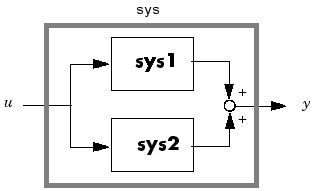

از سینتکس های زیر استفاده کنید

`sys = parallel(sys1,sys2)`

`sys = sys1 + sys2`

#### مثال

دو سیستمی که در قسمت قبل تعریف شده اند را این بار به صورت موازی ببندید

s = tf('s');
sys1 = (s^2 + 3*s + 2) / (s^3 + 2 * s^2 + 3 * s + 1);
sys2 = (s + 2) / (s^2 + 4 * s + 3);
sys = parallel(sys1, sys2)

sys =
 
     2 s^4 + 11 s^3 + 24 s^2 + 24 s + 8
  ----------------------------------------
  s^5 + 6 s^4 + 14 s^3 + 19 s^2 + 13 s + 3
 
Continuous-time transfer function.
Model Properties


sys = sys1 + sys2

sys =
 
     2 s^4 + 11 s^3 + 24 s^2 + 24 s + 8
  ----------------------------------------
  s^5 + 6 s^4 + 14 s^3 + 19 s^2 + 13 s + 3
 
Continuous-time transfer function.
Model Properties


## اتصال فیدبک

اتصال فیدبک زیر

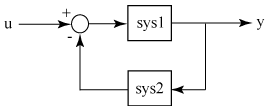

 را میتوانید با سینتکس زیر پیاده کنید

[`sys = feedback(sys1,sys2)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.feedback.html?snc=SCEU3V&searchsource=mw%203p&container=jshelpbrowser#d124e46823)

که در آن

sys1: سیستم در مسیر پیشرو

sys2: تابع تبدیل فیدبک

استفاده از سینتکس زیر پیشنهاد نمیشود، زیرا ممکن است منجر به سیستم نامینیمال (دارای حداقل یک صفر مشابه با یک قطب) شود، در حالی که سیستم فیدبک آن مینیمال است. استفاده از دستور تحقق مینیمال برای حذف صفر و قطب در تابع تبدیل حاصل از آن نیز پیشنهاد نمیشود زیرا ممکن است حذف صفر و قطب در حلقه وجود داشته باشد و نادیده گرفته شود.

sys = sys1  /  (1 + sys1 * sys2)

بنابراین برای اتصال فیدبک حتما از دستور فیدبک استفاده شود

برای تعیین علامت فیدبک نیز میتوانید 1+ یا 1- را به عنوان آخرین آرگومان استفاده کنید، یعنی:

[`sys = feedback(``___``,sign)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.feedback.html?snc=SCEU3V&searchsource=mw%203p&container=jshelpbrowser#d124e46911)

#### مثال


$$G_{\mathrm{plant}} =\frac{1}{s+1},H_{\mathrm{sensor}} =\frac{1}{0\ldotp 001s+1}$$


s = tf('s');
sys1 = 1 / (s+1);
sys2 = 1 / (0.001*s+1);
sys = feedback(sys1, sys2)

sys =
 
        0.001 s + 1
  -----------------------
  0.001 s^2 + 1.001 s + 2
 
Continuous-time transfer function.
Model Properties


حال از سینتکس ضربو تقسیم استفاده میکنیم

sys = sys1 / (1 + sys1 * sys2)

sys =
 
        0.001 s^2 + 1.001 s + 1
  -----------------------------------
  0.001 s^3 + 1.002 s^2 + 3.001 s + 2
 
Continuous-time transfer function.
Model Properties


طبق پیشبینی منجر به تحققی نامینیمال شد

حال به هر دو سیستم تاخیر وارد میکنیم


$$G_{\mathrm{plant}} =\frac{e^{-0\ldotp 3s} }{s+1},H_{\mathrm{sensor}} =\frac{e^{-0\ldotp 005s} }{0\ldotp 001s+1}$$


s = tf('s');
sys1 = exp(-0.3*s) / (s+1);
sys2 = exp(-0.005*s) / (0.001*s+1);
sys = feedback(sys1, sys2)

sys =
 
  A = 
           x1      x2
   x1      -1  -31.25
   x2      32   -1000
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.3  0.005 
 
Continuous-time state-space model.


مدل بدست آمده به دلیل دارا بودن تاخیرهای داخلی، قابل تبدیل به مدل تابع تبدیل و صفر-قطب-بهره نیست زیرا در نمایش تبدیل لاپلاس آنها، تاخیر قابل فاکتور گرفتن نیست

برای تعیین علامت فیدبک (که به طور پیش فرض منفی است) میتوانید بصورت زیر سینتکس را به کار ببرید

sys = feedback(sys1, sys2, -1)

sys =
 
  A = 
           x1      x2
   x1      -1  -31.25
   x2      32   -1000
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.3  0.005 
 
Continuous-time state-space model.


## معکوس سیستم

برای یافتن معکوس یک سیستم که در معادله زیر صدق کند:


$$H*H^{-1\;} =I$$


از دستور زیر استفاده کنید:

Hinv = inv(H)

در سیستمهای تک ورودی تک خروجی


$$H*H^{-1\;} =H^{-1\;} *H=\;I$$


این دستور برای سیستمهای دارای تاخیر کار نخواهد کرد، زیرا معکوس ان سیستمها، سیستمهایی غیر علی هستند

توجه کنید که از این دستور برای بدست آوردن تابع تبدیل حلقه فیدبک استفاده نکنید

`T = inv(1 + g*h) * g`

مشابه دستور زیر رفتار میکند

sys = sys1  /  (1 + sys1 * sys2)

که در مثال بالا رفتار نامطلوب آن را مشاهده کردید

#### مثال


$$G_1 =\frac{s^2 +3s+2}{s^3 +2s^2 +3s+1}$$


sys1 = (s^2 + 3*s + 2) / (s^3 + 2 * s^2 + 3 * s + 1);
sys1_inv = inv(sys1)

sys1_inv =
 
  s^3 + 2 s^2 + 3 s + 1
  ---------------------
      s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


sys = sys1 * sys1_inv

sys =
 
  s^5 + 5 s^4 + 11 s^3 + 14 s^2 + 9 s + 2
  ---------------------------------------
  s^5 + 5 s^4 + 11 s^3 + 14 s^2 + 9 s + 2
 
Continuous-time transfer function.
Model Properties


sys = minreal(sys)

sys =
 
  1
 
Static gain.
Model Properties


اگر نیاز به بلوک بهره دارید، از سینتکس های بالا برای این کار استفاده نکنید زیرا دستوری مناسبتر برای این کار وجود دارد

## اتصال سیستم های پیچیده تر

### دستور اتصال

اگرچه سینتکس های بالا ساده هستند و برای سیستمهای کوچک مناسب است، اما با پیچیده تر شدن اتصالات بلوکهای مختلف، استفاده از دستورات بالا چالش برانگیز خواهد شد. همچنین اشتباه در تشخیص دستور مناسب میتواند منجر به اشتباه در تعریف سیستم در متلب شود. برای حل این مشکل میتوانید هر بلوک را به همراه نام ورودی و خروجی هایش تعیف کنید. سپس از دستور زیر استفاده کنید

`sysc = connect(sys1,...,sysN,inputs,outputs)`

که در آن

sys1: تابع تبدیل بلوک اول

sysN: تابع تبدیل بلوک ان

inputs: نام ورودی مجموعه (بایستی ورودی یکی از بلوکها نیز باشد) که در نهایت ورودی سیستم نهایی خواهد شد

outputs: نام خروجی مجموعه (بایستی خروجی یکی از بلوک ها نیز باشد) که در نهایت خروجی سیستم نهایی خواهد شد

این سینتکس سیستم هایی که به عنوان آرگومان وارد شده اند را با توجه به نام گذاری کاربر متصل میکند. اگر بلوکی دارای خروجی به نام "شتاب" باشد و سیستم دیگری ورودی به نام "شتاب" داشته باشد، این دو به صورت سری متصل میشوند. سیستمهایی به نام یکسان ورودی و خروجی نیز موازی خواهند شد.

جهت استفاده از این دستور برای توپولوژی فیدبک، بایستی بلوک جمع کننده را در صورت وجود تعریف کنید.

### بلوک جمع کننده

مثالی از این بلوک که برای فیدبک و اضاف کردن سیگنالی دیگر به مجموعه بکار میرود، در شکل زیر آورده شده است

سینتکس آن نیز به صورت زیر است

[`S = sumblk(formula)`](https://127.0.0.1:31515/static/help/control/ref/sumblk.html#d124e167980)

#### مثال

بلوک بالا را تعریف کنید


$$u=u_1 +u_2 +u_3$$


blk = sumblk('u = u1 + u2 + u3')

blk =
 
  From input "u1" to output "u":
  1
 
  From input "u2" to output "u":
  1
 
  From input "u3" to output "u":
  1
 
Static gain.
Model Properties


### مثال برای دستور اتصال

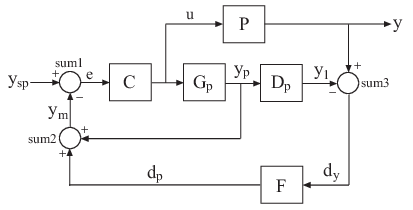


$$P=\frac{5\ldotp 6{\;e}^{-93\ldotp 9\;s} }{40\ldotp 2\;s+1},G_p =\frac{5\ldotp 6}{40\ldotp 2\;s+1},D_p ={\;e}^{-93\ldotp 9\;s} ,F=\frac{1}{20\;s+1},C=0\ldotp 574\;\left(1+\frac{1}{40\ldotp 1\;s}\right)$$


s = tf('s');

P = exp(-93.9*s) * 5.6/(40.2*s+1);
P.InputName = 'u'; P.OutputName = 'y';

Gp = 5.6/(40.2*s+1);
Gp.InputName = 'u'; Gp.OutputName = 'yp';

Dp = exp(-93.9*s);
Dp.InputName = 'yp'; Dp.OutputName = 'y1';

F = 1/(20*s+1);
F.InputName = 'dy'; F.OutputName = 'dp';

C = 0.574*(1+1/(40.1*s));
C.Inputname = 'e'; C.OutputName = 'u';

sum1 = sumblk('e = ysp - ym');
sum2 = sumblk('ym = yp + dp');
sum3 = sumblk('dy = y - y1');

T = connect(P,Gp,Dp,C,F,sum1,sum2,sum3,'ysp','y')

T =
 
  A = 
             x1        x2        x3        x4
   x1  -0.02488  -0.07996   0.05726   -0.0574
   x2         0   -0.1048   0.05726   -0.0574
   x3         0  -0.03483         0    -0.025
   x4   0.06965  -0.06965         0     -0.05
 
  B = 
         ysp
   x1  0.287
   x2  0.287
   x3  0.125
   x4      0
 
  C = 
          x1      x2      x3      x4
   y  0.2786       0       0       0
 
  D = 
      ysp
   y    0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 93.9  93.9 
 
Continuous-time state-space model.
